# AlexNet

                 ***Downloading the AlexNet support package***

 Type " alexnet" in the command window. 

         - If the add-on is NOT installed an error message will appear. Follow that

           prompt to install the add-on.

        - If the add-on is installed the command window will dispay "SeriesNetwork" with properties

Source for code on how to use Alexnet for transfer learning and image classification (Phases 2-5): 

                                     https://www.mathworks.com/help/deeplearning/ref/alexnet.html

**                                                       Phase 1:   Load Data**

imageFolder= '\\client\c$\Documents\BME 3053C\project\brain_tumor_dataset' % update to the your file location

imageFolder = '\\client\c$\Documents\BME 3053C\project\brain_tumor_dataset'

imds = imageDatastore(imageFolder, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
[trainingSet,testSet] = splitEachLabel(imds,0.3,'randomize'); % Divide the data into training and test sets at 30% and 70% respectively


**                                                       Phase 2:   Load the pretrained network**

net = alexnet;
inputSize = net.Layers(1).InputSize

inputSize =    227   227     3


**                                                       Phase 3:   Replace Final Layers**

     *** The last three layers of the pretrained network needs to be refined to accomodate the classifiers in the new data***

layersTransfer = net.Layers(1:end-3);
numClasses = numel(categories(trainingSet.Labels))

numClasses = 2

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];


**                                                       Phase 4:   Train Network**

 *** The image input size for this network needs to be 227 x 227 x 3 so an augmented image datastore is used to resize the images***

 *** A color preprocessing option of 'gray2rgb' was added to augimdsTrain and autestSet to ensure that the images sizes do not 

      differ in the 3rd dimension and that all augmented images have the same number of channels*** 

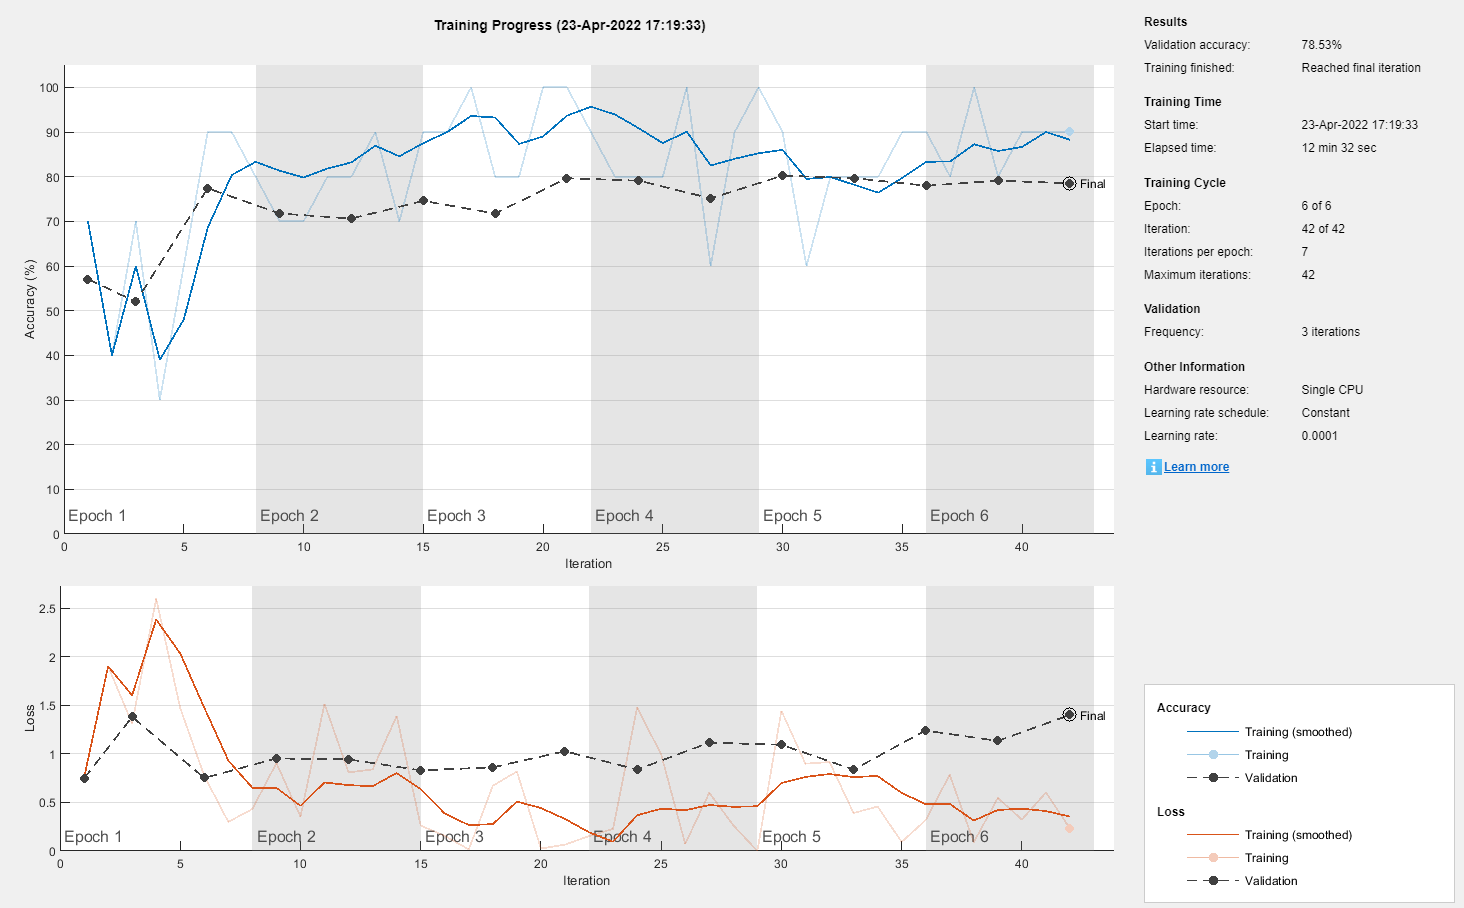

pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),trainingSet, ...  %  Augmented training images
    'DataAugmentation',imageAugmenter,'ColorPreprocessing', 'gray2rgb');  
augtestSet = augmentedImageDatastore(inputSize(1:2),testSet,'ColorPreprocessing', 'gray2rgb');  %  Augmented testing images
options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augtestSet, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');
netTransfer = trainNetwork(augimdsTrain,layers,options);

**                                                      Phase 5: Classify the Test Set**

[YPred,scores] = classify(netTransfer,augtestSet);
YValidation = testSet.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.7853

**                                                      Phase 6: Create Confusion Matrix**

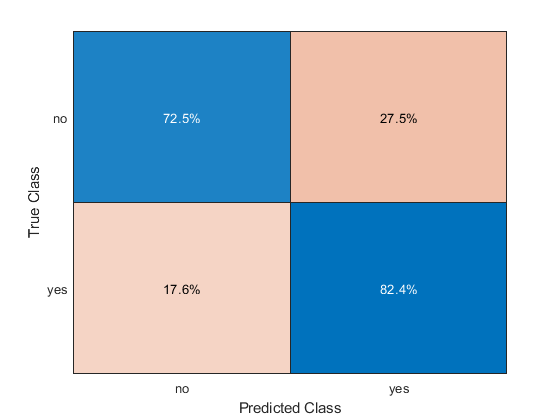

confusionchart(YPred, YValidation,'Normalization', 'row-normalized')